pref =          0         0         0
    0.0010         0         0
    0.0020         0         0
    0.0030         0         0
    0.0040         0         0
    0.0050         0         0
    0.0060         0         0
    0.0070         0         0
    0.0080         0         0
    0.0090         0         0


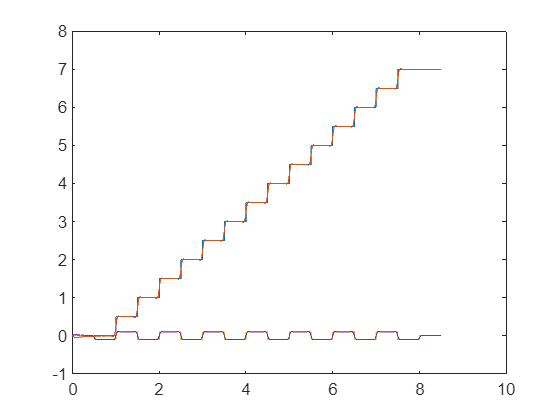

doubleN = 25

Lfoot = 1.0e+10 *

         0         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0
    0.0000         0    0.0000         0


clear
clc

dt=0.001;
q=zeros(9501,13);
q(:,1)=0:dt:9.5;

%下蹲
Tsqu=0.5; %下蹲时间
Hmax=1.225; %0位质心高度
Hwalk=1.15; %下蹲后质心高度

for i=1:round(Tsqu/dt)
    t=(i-1)*dt;
    A=Hwalk-Hmax; %高度变化量

    %多项式插值函数选择
    %五次多项式插值
    [a,~,~] = Quintic_polynomial_interpolation_general(0,A,0,0,0,0,Tsqu,t); 
    %三次多项式插值
     % [a,~,~] = Cubic_polynomial_interpolation(0,A,0,0,Tsqu,t);

    pc=[0,0,Hmax+a];
    pfl=[0,0.1,0];
    [L_Hip_Yaw,L_Hip_Roll,L_Hip_Pitch,L_knee,L_Ankle_Pitch,L_Ankle_Roll]=ik(pc,pfl,1);
    pfr=[0,-0.1,0];
    [R_Hip_Yaw,R_Hip_Roll,R_Hip_Pitch,R_knee,R_Ankle_Pitch,R_Ankle_Roll]=ik(pc,pfr,2);
    q(500+i,2:13)=...
    [L_Hip_Yaw,L_Hip_Roll,L_Hip_Pitch,L_knee,L_Ankle_Pitch,L_Ankle_Roll,R_Hip_Yaw,R_Hip_Roll,R_Hip_Pitch,R_knee,R_Ankle_Pitch,R_Ankle_Roll];
end

%行走
gait=generate_gait();

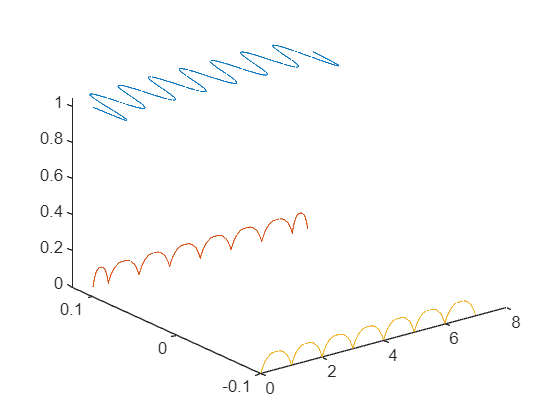

for i=1:size(gait,1)
    pc=[gait(i,2),gait(i,3),Hwalk];
    pfl=gait(i,4:6);
    pfr=gait(i,11:13);
%膝关节角度
    [L_Hip_Yaw,L_Hip_Roll,L_Hip_Pitch,L_knee,L_Ankle_Pitch,L_Ankle_Roll]=ik(pc,pfl,1);  
    [R_Hip_Yaw,R_Hip_Roll,R_Hip_Pitch,R_knee,R_Ankle_Pitch,R_Ankle_Roll]=ik(pc,pfr,2);
    q(1000+i,2:13)=[L_Hip_Yaw,L_Hip_Roll,L_Hip_Pitch,L_knee,L_Ankle_Pitch,L_Ankle_Roll,R_Hip_Yaw,R_Hip_Roll,R_Hip_Pitch,R_knee,R_Ankle_Pitch,R_Ankle_Roll];
end
figure
H=ones(8501, 1) * Hwalk-a;
plot3(gait(:,2)+(0)+(0),gait(:,3)+( 0)+(0.1),H+( -0.175));
hold on 
plot3(gait(:,4)+(0),gait(:,5)+(0),gait(:,6)+(.05));
hold on 
plot3(gait(:,11),gait(:,12),gait(:,13));
hold off

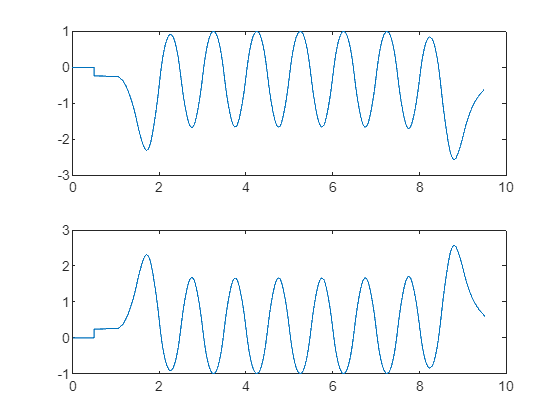

figure 
subplot(2,1,1);
plot(q(:,1),q(:,3)*180/pi);
subplot(2,1,2);
plot(q(:,1),q(:,7)*180/pi);

function [L_Hip_Yaw,L_Hip_Roll,L_Hip_Pitch,L_knee,L_Ankle_Pitch,L_Ankle_Roll]=ik(pc,pf,lr)
%腿部逆运动学
%已知质心位置pc，脚底中心位置pf，计算左腿关节角度
%输出结果为从上到下依次关节角度，默认膝关节前弯
% pc=[0,0,Hmax-a];
% 
%    pf=[0.00055,-0.095,0];
if lr==1 %左腿
    phip=pc+[-0.0011  0.095  -0.013327] ;%髋关节位置  [-0.0011  0.095  -0.013327]

    phip2_roll=phip+[-0.00185, 0,   -0.024];
    knee=phip2_roll+[ 0,        -0.00525,  -0.02315]+[ -0.0045,   0.0000,  -0.128];
     pankle=pf-[ 0, 0, -0.037];

else %右腿
    phip=pc+[-0.0011 -0.095 -0.013327]; %髋关节位置 [-0.0011 -0.095 -0.013327 ]
    phip2_roll=phip+[ -0.00185,  0,   -0.024];

    knee=phip2_roll+[ 0         ,0.00525,  -0.02315]+[  -0.0045,   0.0000,  -0.128];
    pankle=pf-[ 0, 0, -0.037];
end

%% 三杆长度计算
 l2 =0.1183;
 l1=norm(phip-knee);

 %踝关节位置   
Lleg = norm(pankle-phip)+3.813e-04; %腿长  
Rleg=norm([phip2_roll(2),phip2_roll(3)]-[pf(2),pf(3)]);

%膝关节角度
  % L_knee1=pi-2*asin(Lleg);  % Π -2

%% 三角形几何解
% L_knee=(-acos((l1^2+l2^2-Lleg^2)/(2*l1*l2))+pi);
% L_Ankle_Pitch=-asin((l1*sin(pi-L_knee)/Lleg));

L_knee = (-acos(max(-1, min(1, (l1^2 + l2^2 - Lleg^2) / (2 * l1 * l2)))) + pi);
% L_Ankle_Pitch =asin((knee(1)-pankle(1)+0.008)/l2)+0.5*L_knee;
 % L_Ankle_Pitch=-asin(max(-1,min(1,(pankle(1)-phip(1)/Lleg ))));+asin((abs(pankle(1)-phip(1)-0.00165)/Lleg));asin(abs(knee(1)-pankle(1))/l2);
% L_Hip_Pitch=L_knee-abs(asin(max(-1, min(1, (l1 * sin(pi - L_knee) / Lleg)))))+asin(abs(pankle(1)-phip(1)-0.00165)/Lleg);+atan((pankle(1)-phip(1)-0.00055)/(-pankle(3)+phip(3)))
L_Hip_Pitch=acos(max(-1, min(1, (l1^2 + Lleg^2 - l2^2) / (2 * l1 * Lleg))));
L_Ankle_Pitch =L_knee-L_Hip_Pitch;

%% 侧摆
% L_Hip_Roll=-asin((abs(pf(2)-phip2_roll(2))-0.0055)/norm(phip2_roll(2:3)-pf(2:3)));
L_Hip_Roll=asin((phip2_roll(2)-pf(2))/Rleg);
L_Ankle_Roll=-L_Hip_Roll;
L_Hip_Yaw=0;

end

function [q_,qd,qdd]= Quintic_polynomial_interpolation_general(q0,q1,qd0,qd1,qdd0,qdd1,T,t)  
%%  q1(A)     qdd1(Tsqu)  t(t)
%给定初末位置、速度、加速度、总时间，返回五次插值后，
% 在时间t（0<t<T）的位置、速度、加速度，t也可以是时间序列
A=[0       0        0        0       0       1;
   T^5     T^4      T^3      T^2     T       1;
   0       0        0        0       1       0;
   5*T^4   4*T^3    3*T^2    2*T     1       0;
   0       0        0        2       0       0;
   20*T^3  12*T^2   6*T      2       0       0];
B=[q0;q1;qd0;qd1;qdd0;qdd1];  %%[ 0 A 0 0 0 0 ]
p=A\B;
q_=p(1,:)'*t.^5+p(2,:)'*t.^4+p(3,:)'*t.^3+p(4,:)'*t.^2+p(5,:)'*t+p(6,:)';
qd=5*p(1,:)'*t.^4+4*p(2,:)'*t.^3+3*p(3,:)'*t.^2+2*p(4,:)'*t+p(5,:)';
qdd=20*p(1,:)'*t.^3+12*p(2,:)'*t.^2+6*p(3,:)'*t+2*p(4,:)';
end 

function gait=generate_gait()
%开始-步行-停止模式，获得重心位置和足底位置随时间的变化
W0=0.2;                   %胯宽
zc=1;                     %质心高度
Tstep=0.5;                %半步周期
double_support_ratio=0.1; %双支撑时间占比
Lstep=0.5;                %步长
Nstep=15;                 %半步数
dt=0.001;                 %时间步长
H=0.1;                    %抬脚高度

Ttot=Tstep*(Nstep+2);  %前后各增加一个周期用于稳定 0.5*(15+2)=8.5
t=0:dt:Ttot;           % 1: 8501

%ZMP
pref=zeros(length(t),3) ;%第一列是时间，第二列是ZMP的x，第三列是ZMP的y
pref(:,1)=t';
for i=2:Nstep+1  %2:16
    if mod(i,2)==0    % 取余  偶数步 左腿支撑
        pref((i-1)*round(Tstep/dt)+2:i*round(Tstep/dt),3)=-W0/2;
    else    %单数步，右腿支撑
        pref((i-1)*round(Tstep/dt)+2:i*round(Tstep/dt),3)=W0/2;
    end
    pref((i-1)*round(Tstep/dt)+2:i*round(Tstep/dt)+1,2)=(i-2)*Lstep;
end
pref((Nstep+1)*round(Tstep/dt)+2:end,2)=(i-2)*Lstep %最后一个周期 8001开始

%质心位置计算
gaitx=Preview_Control_Improvement(pref(:,2)',zc,dt);
gaity=Preview_Control_Improvement(pref(:,3)',zc,dt);


%铺脚印
Lfoot=zeros(length(t),4); %左脚的txyz
Lfoot(:,1)=t';
Lfoot(:,2)=10^10;
Lfoot(:,3)=W0/2;
Rfoot=zeros(length(t),4); %左脚的txyz
Rfoot(:,1)=t';
Rfoot(:,2)=10^10;
Rfoot(:,3)=-W0/2;
doubleN=round(double_support_ratio*(Tstep/dt)/2) % 25
%初始双支撑时间
Lfoot(1:round(Tstep/dt)+doubleN,2)=pref(1,2);   % 1~525
Rfoot(1:round(Tstep/dt)+doubleN,2)=pref(1,2);   % 1~525
for i=1:length(t)-1
    if pref(i,3)==0&&pref(i+1,3)>0 %左脚落地时刻    
        if i+1-doubleN<0  %在支撑期间
            Lfoot(:,2)=pref(i+1,2);
        else
            Lfoot(i+1-doubleN:end,2)=pref(i+1,2);
        end
    end

    if pref(i,3)>0&&pref(i+1,3)==0 %左脚离地时刻
        if i+1+doubleN<length(t)
            Lfoot(i+1+doubleN:end,2)=10^10;
        end
    end

    if pref(i,3)==0&&pref(i+1,3)<0 %右脚落地时刻   第一时刻①
        if i+1-doubleN<0
            Rfoot(:,2)=pref(i+1,2);
        else
            Rfoot(i+1-doubleN:end,2)=pref(i+1,2);
        end
    end

    if pref(i,3)<0&&pref(i+1,3)==0 %右脚离地时刻
        if i+1+doubleN<length(t)
            Rfoot(i+1+doubleN:end,2)=10^10;
        end
    end
end
%结束 双支撑
Lfoot(length(t)-round(Tstep/dt)-doubleN:end,2)=pref(end,2)  %-525     7976~8501
Rfoot(length(t)-round(Tstep/dt)-doubleN:end,2)=pref(end,2);

%离地区间插值
%左腿
while 1==1
    a0=[];
    for i=1:length(t)-1
        if Lfoot(i,2)<10^10-1 && Lfoot(i+1,2)>10^10-1 %左脚离地
            a0=Lfoot(i,2);
            t0=i;%525  
        end
        if Lfoot(i,2)>10^10-1 && Lfoot(i+1,2)<10^10-1 %左脚着地
            a1=Lfoot(i+1,2);
            t1=i+1;
        end
    end
    if isempty(a0) %检查输入的变量是否为空
        break
    else

    %多项式插值函数选择
      %五次多项式插值
         [q_,qd,qdd]= Quintic_polynomial_interpolation_general(a0,a1,0,0,0,0,t1-t0,(t0:t1)-t0);
       %三次多项式插值
        % [q_,qd,qdd]= Cubic_polynomial_interpolation(a0,a1,0,0,t1-t0,(t0:t1)-t0);

        Lfoot(t0:t1,2)=q_;
        Lfoot(t0:t1,5)=qd;
        Lfoot(t0:t1,6)=qdd; 

    %多项式插值函数选择
     % 五次多项式插值
       [q1,qd1,qdd1]= Quintic_polynomial_interpolation_general(0,H,0,0,0,0,round((t1-t0)/2),(t0:t0+round((t1-t0)/2))-t0);
       [q2,qd2,qdd2]= Quintic_polynomial_interpolation_general(H,0,0,0,0,0,t1-(t0+round((t1-t0)/2)+1),(t0+round((t1-t0)/2)+1:t1)-(t0+round((t1-t0)/2)+1));
       % %三次多项式插值 
       %   [q1,qd1,qdd1]= Cubic_polynomial_interpolation(0,H,0,0,round((t1-t0)/2),(t0:t0+round((t1-t0)/2))-t0);
       %   [q2,qd2,qdd2]= Cubic_polynomial_interpolation(H,0,0,0,t1-(t0+round((t1-t0)/2)+1),(t0+round((t1-t0)/2)+1:t1)-(t0+round((t1-t0)/2)+1));

        Lfoot(t0:t1,4)=[q1,q2];
        Lfoot(t0:t1,7)=[qd1,qd2];
        Lfoot(t0:t1,8)=[qdd1,qdd2];

    end
end
%右腿
while 1==1
    a0=[];
   
    for i=1:length(t)-1
        if Rfoot(i,2)<10^10-1 && Rfoot(i+1,2)>10^10-1 %左脚离地
            a0=Rfoot(i,2);
            t0=i;
        end
        if Rfoot(i,2)>10^10-1 && Rfoot(i+1,2)<10^10-1 %左脚着地
            a1=Rfoot(i+1,2);
            t1=i+1;
           
        end
          
    end
    if isempty(a0)
        break
    else

    %多项式插值函数选择
         %五次多项式插值
         [q_,qd,qdd]= Quintic_polynomial_interpolation_general(a0,a1,0,0,0,0,t1-t0,(t0:t1)-t0);
        %  %三次多项式插值
        % [q_,qd,qdd]= Cubic_polynomial_interpolation(a0,a1,0,0,t1-t0,(t0:t1)-t0);

        Rfoot(t0:t1,2)=q_;
        Rfoot(t0:t1,5)=qd;
        Rfoot(t0:t1,6)=qdd; 

    %多项式插值函数选择
      %五次多项式插值
        [q1,qd1,qdd1]= Quintic_polynomial_interpolation_general(0,H,0,0,0,0,round((t1-t0)/2),(t0:t0+round((t1-t0)/2))-t0);
        [q2,qd2,qdd2]= Quintic_polynomial_interpolation_general(H,0,0,0,0,0,t1-(t0+round((t1-t0)/2)+1),(t0+round((t1-t0)/2)+1:t1)-(t0+round((t1-t0)/2)+1));
     %     %三次多项式插值 
     % [q1,qd1,qdd1]= Cubic_polynomial_interpolation(0,H,0,0,round((t1-t0)/2),(t0:t0+round((t1-t0)/2))-t0);
     %   [q2,qd2,qdd2]= Cubic_polynomial_interpolation(H,0,0,0,t1-(t0+round((t1-t0)/2)+1),(t0+round((t1-t0)/2)+1:t1)-(t0+round((t1-t0)/2)+1));

        Rfoot(t0:t1,4)=[q1,q2];
        Rfoot(t0:t1,7)=[qd1,qd2];
        Rfoot(t0:t1,8)=[qdd1,qdd2];

    end
end
gait=[t',gaitx(:,4),gaity(:,4),Lfoot(:,2:8),Rfoot(:,2:8)];
end

function gait=Preview_Control_Improvement(pref,zc,dt)
% 模型预测控制MPC
% 输入参数说明：pref是ZMP参考位置（期望落脚点，一维随时间变化数据），zc是质心高度 1，dt是控制时间步长
% 输出参数包括：时间序列，参考ZMP位置，实际ZMP位置，实际质心位置（根据ZMP模型预测控制计算得到）
g=9.8;
T=(length(pref)-1)*dt  ;%% 8.5
t=0:dt:T   ;   %0.001

N=5000; %考虑未来的步数
pref=[pref,ones(1,N)*pref(end)];  %1*(8501+5000)

Q=1000; %权重系数
R=1;    %权重系数
A=[1,dt,dt^2/2;0,1,dt;0,0,1];
B=[dt^3/6,dt^2/2,dt]';
C=[1,0,-zc/g];
Ap=[1,C*A; zeros(3,1),A];
Bp=[C*B;B];
Cp=[1 0 0 0];
QQ=Cp'*Q*Cp;
[Kp,Pp,~]=dlqr(Ap,Bp,QQ,R,0);  %离散线性二次型调节器(`dlqr`)

fp=zeros(1,N);
for i=1:N
    fp(i)=pinv(R+Bp'*Pp*Bp)*Bp'*((Ap-Bp*Kp)')^(i-1)*Cp'*Q ;%伪逆函数，用于计算矩阵的广义逆
end

% u=zeros(1,length(t)) ;  %输入量dddot(x)
du=zeros(1,length(t));
x=zeros(3,length(t)); %质心位置、速度、加速度的列向量
dx=zeros(3,length(t));
p=zeros(1,length(t));  %ZMP位置
xs=[p;dx]; % 4*8501

for i=1:length(t)
    du(i)=-Kp*xs(:,i)+fp*[pref(i+1:i+N)]';
    xs(:,i+1)=Ap*xs(:,i)+Bp*du(i);
    dx(:,i+1)=xs(2:4,i+1);
    x(:,i+1)=x(:,i)+dx(:,i+1);
    p(i)=Cp*xs(:,i);
end

plot(t,pref(1:length(t)));  %期望ZMP
hold on
plot(t,p);  %期望ZMP
% % hold on 
% subplot(3,1,1);
% plot(t,x(1,1:length(t)),'LineWidth',2); %质心位置
% xlabel("前行方向x/m")
% ylabel("前行方向y/m")
% title("规划的质心位置图")
% grid on
% 
% subplot(3,1,2);
% plot(t,x(2,1:length(t)),'LineWidth',2); %质心速度
% xlabel("时间t/s")
% ylabel("轨迹速度v(m/s)")
% title("规划的质心速度图")
% grid on
% 
% subplot(3,1,3);
% plot(t,x(3,1:length(t)),'LineWidth',2); %质心速度
% xlabel("时间t/s")
% ylabel("轨迹加速度v(m/s^2)")
% title("规划的质心加速度图")
% 
% sgtitle('规划的质心轨迹图');

% hold on
% legend('期望ZMP','实际ZMP','质心位置')

gait=[t',pref(1:length(t))',p',x(1,1:length(t))'] ;%(时间 ，期望ZMP，实际ZMP，质心位置)

end